# Analisis dinámico del drone

clear; clc


% Especificaciones: 
% DJI Air 2S (en modo N) https://www.dji.com/es/air-2s/specs

% masa
m = 0.595;      % kg
g = 9.8;        % m/s²
Fg = m*g;       % peso en N

% Inercia de caja 20x20x3 cm3
% En realidad nuestro dron ocupa una caja de 25x25x4.5 cms
Ix = 1/12 * m * (0.20^2 + 0.03^2);
Iy = 1/12 * m * (0.20^2 + 0.03^2);
Iz = 1/12 * m * (0.20^2 + 0.20^2);

## Fuerza de empuje aerodinamico

Asumimos comportamiento de Motor MT2814 770KV con hélice APC10*3.8  [https://www.thanksbuyer.com/high-performance-brushless-t-motor-mt2814-710kv-770kv-for-copter-12225](https://www.thanksbuyer.com/high-performance-brushless-t-motor-mt2814-710kv-770kv-for-copter-12225)

% Segun dicha pagina, el motor genera esta fuerza a partir de su giro
rpm1 = [4430 5100 5975 6420 7030];  % en rpm
T1   = [350   500  690  820 1000];  % en gramos
clf
plot(rpm1,T1,'o-')
grid on
hold on
xlim([0 8000])
ylim([0 1400])
xlabel('RPM')
ylabel('gramos')

% lo ajustamos con la expresión FT = kFT * w²
ref = 2;
w_ref = convangvel(rpm1(ref),'rpm','rad/s'); 
T_ref = T1(ref)/1000;
kFT = T_ref * g / w_ref^2  

kFT = 1.7179e-05

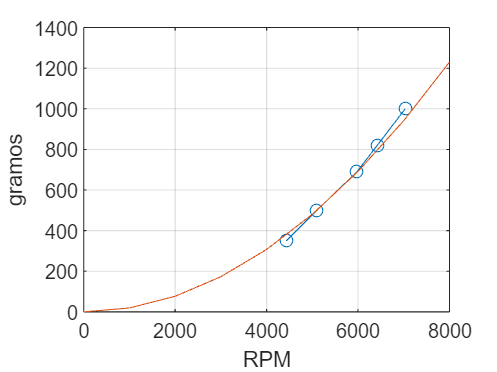

rpm2 = 0:1000:8000;
radps = rpm2 / 60 * 2 * pi;
T2 = kFT * radps.^2;
T2 = T2 / 9.8 * 1000;
plot(rpm2,T2)


% Asumimos velocidad maxima del motor
w_max = convangvel(6000,'rpm','rad/s') % 628.3185 rad/s  -------------

w_max = 628.3185

% y obtenemos  
FT_max = kFT * w_max.^2 ;   % fuerza maxima de cada rotor: 6.782N = 692grs 
rel = 4 * FT_max / Fg;      % relación empuje/peso:  4.65:1

% velocidad del rotor para que los 4 rotores mantengan la sustentacion
w_hov = sqrt(Fg/4 /kFT)     % 291.3012rad/s = 2781rpm

w_hov = 291.3012


% velocidad del rotor para que solo 2 rotores opuestos mantengan la sustentacion
w_hov2 = sqrt(Fg/2 /kFT);   % 411.9621rad/s = 3933rpm
% !!!! esto no es cierto!!!!
% no es lineal, es cuadrático. no puedes dividir por dos!!!

## Fuerza de arrastre aerodinamico

Eje horizonte: Asumimos rozamiento similar en ambos ejes (aunque el fuselaje no sea igual)

% DJI establece la velocidad máxima horizontal en 25m/s
% nosotros deberemos acotar tambien

Vh_max = 25; % m/s = 54km/s segun DJI
% angulo máximo de inclinación
angle_max = 30; % grados segun DJI
% en consecuencia, cuando vuela a velocidad máxima con maxima inclinacion, los motores actuan a
FT_Vh_max = Fg / cosd(angle_max);
w_Vh_max = sqrt(FT_Vh_max/4 /kFT);   % 309.9422 rad/s = 2960 rpm


FD_Vh_max = Fg / sind(angle_max);    % 11.6620N  
% por tanto queda que...
kFDxy = FD_Vh_max / w_Vh_max^2       % 1.2140e-04 -------------------------

kFDxy = 1.1902e-04



% Eje vertical:
% Teniendo en cuenta la velocidad máxima de descenso
%   humano cae a 55m/s
%   gota   cae a 10m/s
% Asumimos
%   drone  cae a 40m/s
VzDOWN_max = 40;
% en consecuencia, cuando vuela a velocidad máxima de ascenso, los motores actuan a
kFDz = Fg / VzDOWN_max^2           % 36e-04 --------------------------

kFDz = 0.0036

% DJI establece la velocidad máxima vertical en 6m/s
% nosotros deberemos acotar tambien

% En definitiva
kFD  = [kFDxy  0    0  ;
          0  kFDxy  0  ; 
          0    0  kFDz ];

## Momento de empuje aerodinamico

Se calcula directamente. Solo es necesario

L = 0.075;   % los 4 rotores están situados en un cuadrado de 15 cms de lado centrado en el centro de masas

## Momento de arrastre de los rotores

Momento que experimenta el rotor en sentido contrario a su velocidad de giro MDR = kMDR * w² Asumimos que - no hay rozamiento con el aire - el dron estabilizado comienza a girar con maxima aceleración empleando 2 motores - en 2s alcanza una velocidad de 1 vuelta por segundo = 2*pi rad/s

acel_ang = 2*pi / 2;        % aceleración angular necesaria
MDR2 = Iz * acel_ang;       % momento angular necesario
MDR1 = MDR2 / 2;            % momento angular proporcionado por cada rotor
kMDR = MDR1 / w_hov2^2      % 3.7448e-08

kMDR = 3.6714e-08


% DJI establece la velocidad máxima de rotación del dron en 90°/s
% nosotros deberemos acotar tambien

## Momento de arrastre aerodinamico

Momento de rozamiento con el aire que sufre el drone al girar. Es contrario a la velocidad angular. 

MD = -kMD * rpy_dot * `rpy_dot` depende de la forma del objeto en cada eje.

% Ejes horizontales:
% Asumimos 
%   rozamiento similar en ambos ejes (aunque el fuselaje no sea igual)
%   escenario sin gravedad
%   los motores actuan a velocidad de sustentación
%   pero los motores de un lado estan invertidos!!
%   el dron adquiere una velocidad angular terminal de 10 vueltas/s
%   cuando MD = MT
vel_ang_max = 10* 2*pi;  % rad/s
% operando
MDxy = Fg * L; % momento angular de los motores
kMDxy = MDxy / vel_ang_max^2 % 1.1077e-04

kMDxy = 1.1078e-04


% Eje vertical:
% Asumimos 
%   escenario con gravedad
%   2 motores opuestos actuan a velocidad de sustentación
%   el dron adquiere una velocidad angular terminal de 2 vueltas/s
%   cuando MD = MT
vel_ang_max = 2 * 2*pi;  % rad/s
% operando
MDz  = MDR2;                % momento angular de los motores
kMDz = MDz / vel_ang_max^2 % = 7.8914e-05

kMDz = 7.8914e-05


% En definitiva
kMD  = [kMDxy   0     0  ;
          0   kMDxy   0  ; 
          0     0   kMDz ];

## Servosistema con realimentacion controlada de estado y salida

% load('linsys_x08y04_OLD.mat')
% Aold = linsys_x08y04.a;
% Bold = linsys_x08y04.b;
% Cold = linsys_x08y04.c;

load('linsys1.mat')
A = linsys1.a;
B = linsys1.b;
C = linsys1.c;



% disp('Autovalores de A:');
% disp(eig(A));
%  
% disp('Dimension de A:');
% disp(length(A));
% disp('Rango de matriz de controlabilidad:');
% disp(rank(ctrb(A,B)));


AA = [ A  zeros(8,4) ;
       C  zeros(4,4) ];
   
BB = [ B          ;
       zeros(4,4) ];
   
% disp('DimensiOn de AA:');
% disp(length(AA));
% disp('Rango de matriz de controlabilidad:');
% disp(rank(ctrb(AA,BB)));


%PP = [-6 -6 -7 -7 -8 -8 -8 -8 -9 -9 -9 -9]; % Drone Challenge version definitiva usada
% PP = [-1 -1 -2 -2 -3 -3 -3 -3 -4 -4 -4 -4]; % Drone Challenge 2023
PP = [-2 -2 -3 -3 -4 -4 -4 -4 -5 -5 -5 -5]; % Drone Challenge 2023
KK = place(AA,BB,PP);
Kx = KK(:,1:8)

Kx =   -47.4820  -47.4820   -9.3626   -9.3626  413.1508  -10.5091   10.5091  132.4440
   47.4820  -47.4820    9.3626   -9.3626 -413.1508  -10.5091  -10.5091  132.4440
  -47.4820   47.4820   -9.3626    9.3626 -413.1508   10.5091   10.5091  132.4440
   47.4820   47.4820    9.3626    9.3626  413.1508   10.5091  -10.5091  132.4440


Ki = KK(:,9:12)

Ki =    -8.1889    8.1889  294.3201  918.1130
   -8.1889   -8.1889  294.3201 -918.1130
    8.1889    8.1889  294.3201 -918.1130
    8.1889   -8.1889  294.3201  918.1130


## Ejemplos de iteración de control

Drone suspendido en el aire

% vector de estado
x0 =[ 0   % ePhi
      0   % eTheta
      0   % bWx
      0   % bWy
      0   % bWz
      0   % bXdot
      0   % bYdot
      0   % bZdot
];


% vector de salida
y = [ 0   % bXdot
      0   % bYdot
      0   % bZdot
      0   % bWz
];      

r = [ 0   % bXdot
      0   % bYdot
      0   % bZdot
      0   % hZdot
];

e = y - r

e =      0
     0
     0
     0



interval = 0;

E = [0 0 0 0]';
E = E + (e * interval);


% Wr = Hs - Kx * x - Ky * E

